## Numerical comparison

This notebook aims to numerically compare some ODE solvers. Due to Lotka-Volterra not having a closed form solution, their convergence order will be numerically aproximated using self-convergence testing. A function is implemented to test it. It uses a struct that completely defines the problem, to make the code more readable.

function p = ODE_test(IVP, N, iter, method)
%ODE_test Implements Richardson convergence analysis to aproximate
% convergence order

arguments
    IVP struct
    N (1,1) double {mustBeInteger}
    iter (1,1) double {mustBeInteger}
    method (1,1) function_handle
end

f = IVP.ode;
iv = IVP.iv;
t_start = IVP.t_start;
t_end = IVP.t_end;
err = zeros(1,iter+1);

for i = 0:iter
    n = N*2^i;
    [~, x] = method(f, t_start, t_end, iv, n);
    [~, x2] = method(f, t_start, t_end, iv, 2*n);
    err(i+1) = norm(x(:,1)-x2(1:2:end,1), inf);
end

e1 = err(1:end-1);
e2 = err(2:end);

p = log(e1./e2)/log(2);

end

Using this function, the various ODE solvers can be tested.

IVP = struct( ...
    'ode', [], ...
    't_start', [], ...
    't_end', [], ...
    'iv', [] ...
    );

a = 0.5; b = 0.02; c = 0.01; d = 0.4;
predator = 40; prey = 10;
IVP.ode = LotkaVolterra(a,b,c,d);
IVP.t_start = 0;
IVP.t_end = 10;
IVP.iv = [predator; prey];

Euler = ODE_test(IVP, 10, 5, @Euler)

Euler =     1.5680    1.2603    1.1420    1.0729    1.0378


AdamsBashfort = ODE_test(IVP, 10, 5, @AdamsBashforth)

AdamsBashfort =     1.9568    2.0980    1.9917    1.9872    1.9907


RK4 = ODE_test(IVP, 10, 5, @RungeKutta)

RK4 =     3.9980    3.9791    3.9678    3.9832    3.9915


DormandPrince = ODE_test(IVP, 10, 5, @DormandPrince)

DormandPrince =     6.5154    5.8117    5.5196    5.3225    5.1860


It can be seen that all methods have the expected convergence order, showing how this problem is well behaved. However, using too high numbers of iterations will make the higher order's methods value to collapse, due to rounding error being much higher than the actual error for the method.

## Computational cost comparison

Compute time can also be compared between methods, as a lower order method might be more suitable in certain situations, where moderate degrees of precision are required, but computation time being lower is useful.

function [t,n] = compute_time(IVP, N, iter, method)

arguments
    IVP struct
    N (1,1) double {mustBeInteger}
    iter (1,1) double {mustBeInteger}
    method (1,1) function_handle
end

f = IVP.ode;
iv = IVP.iv;
t_start = IVP.t_start;
t_end = IVP.t_end;
t = zeros(1,iter);
n = N*2.^(1:iter);

for i = 1:iter
    start = cputime;
    [~, ~] = method(f, t_start, t_end, iv, n(i));
    t(i) = cputime - start;
end
end

Comparing the previous methods on compute time yields the following results

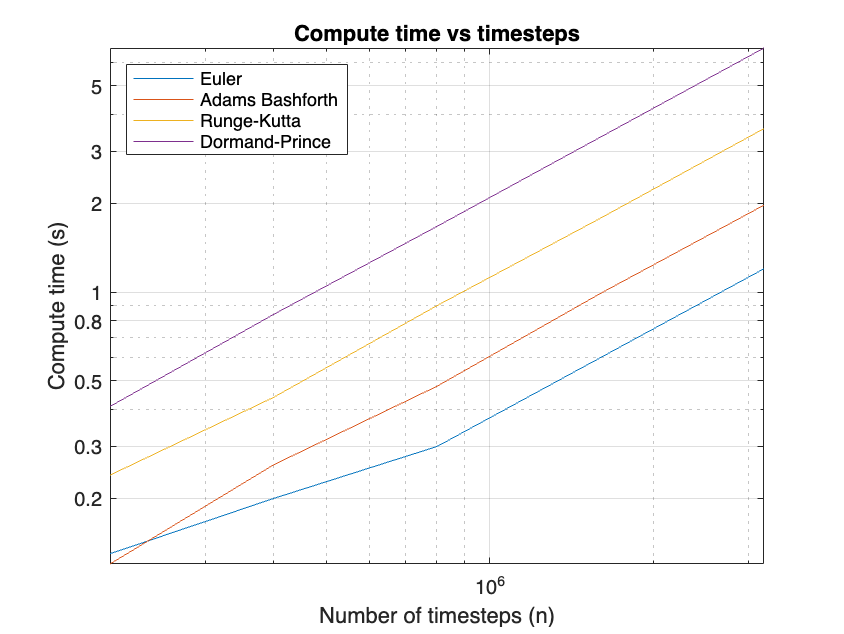

IVP = struct( ...
    'ode', [], ...
    't_start', [], ...
    't_end', [], ...
    'iv', [] ...
    );

a = 0.5; b = 0.02; c = 0.01; d = 0.4;
predator = 40; prey = 10;
IVP.ode = LotkaVolterra(a,b,c,d);
IVP.t_start = 0;
IVP.t_end = 10;
IVP.iv = [predator; prey];

N = 1e5; iter = 5;
Euler = compute_time(IVP, N, iter, @Euler);
AdamsBashfort = compute_time(IVP, N, iter, @AdamsBashforth);
RK4 = compute_time(IVP, N, iter, @RungeKutta);
[DormandPrince, n] = compute_time(IVP, N, iter, @DormandPrince);

loglog(n,Euler)
hold on
loglog(n,AdamsBashfort)
loglog(n,RK4)
loglog(n,DormandPrince)
hold off

title("Compute time vs timesteps")
legend("Euler","Adams Bashforth", "Runge-Kutta","Dormand-Prince",Location="northwest")
grid
xlabel("Number of timesteps (n)")
ylabel("Compute time (s)")
xlim([n(1) n(end)])

yticks([0.2 0.3 0.5 0.8 1 2 3 5 8])
set(gca,'YScale','log')

Despite the lower order methods being faster, the difference is under an order of magnitude even when compared to the highest order method here, due to all of them relying on relatively simple vectorized operations. Thus, it is unlkely that any application would need such high speeds and low precisions for the lower order methods to be better suited.